x = [3 2 4];
y = [4 3 2];
r = 5;
t = 2*pi*rand(1,3)

t =     5.2203    3.6773    3.4540


u = 0.03*cos(t)

u =     0.0146   -0.0258   -0.0285


v = 0.03*sin(t)

v =    -0.0262   -0.0153   -0.0092


test 

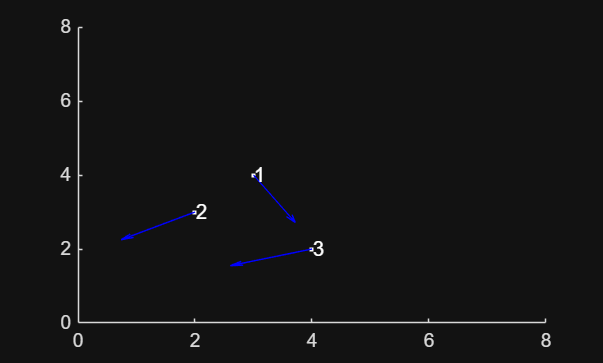

scatter(x, y, 'white.');
hold on;
quiver(x,y,u,v, 'blue');
for i = 1:3
    text(x(i)+0.01, y(i)+0.01, string(i), 'Color','white');
end
xlim([0 8])
ylim([0 8])
hold on;

neighbours_of_i = find_neighbours(1, x, y, r, 3)

neighbours_of_i =      2     3


[theta_average, xt1, yt1] = diksuchi(1, x, y, u, v, neighbours_of_i, 0.02, 1, 0.05,8)

u_n =    -0.0258   -0.0285


v_n =    -0.0153   -0.0092


theta_average = 3.5740

xt1 = 2.0920

yt1 = 3.5809

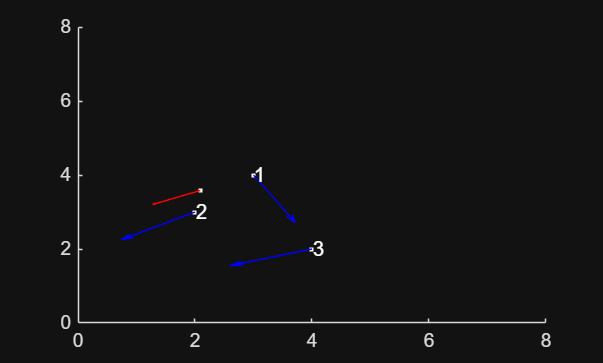

scatter(xt1, yt1, "white.")
quiver(xt1, yt1, cos(theta_average), sin(theta_average), "red" )
hold off;

function neighbours = find_neighbours(poi_n, x, y, r, N)
    %poi = particle of interest
    x_n = zeros(1, N);
    y_n = zeros(1, N);
    poi_x = x(poi_n);
    poi_y = y(poi_n);
    n_coords = zeros(1, N);
    for i = 1:N
        if (poi_y-r)< y(i) && y(i) < (poi_y+r)
            if (poi_x-r)< x(i) && x(i) < (poi_x+r)
                dist = sqrt((y(i)-poi_y)^2 + (x(i)-poi_x)^2);
                if dist < r && dist > 0
                    y_n(i) = y(i);
                    x_n(i) = x(i);
                    n_coords(i) = i;
                end
            end
        end
    end
    neighbours = n_coords(n_coords ~= 0);
end

function [theta_avg, x_t1, y_t1] = diksuchi(poi_n, x, y, u, v, neighbours, eta, velocity, epsilon, L)
    n = neighbours;
    no_n = numel(n);
    
    if no_n > 0 
        u_n = zeros(1,no_n);
        v_n = zeros(1,no_n);
        for i = 1:no_n
            u_n(i) = u(n(i));
            v_n(i) = v(n(i));
        end
    else 
        u_n = u;
        v_n = v;
    end
    u_n
    v_n
    noise = -eta/2 + eta*rand(1);
    a = mean(v_n);
    c = mean(u_n);
    theta_avg = atan(a/c) + noise;
    if a < 0 && c < 0
        theta_avg = theta_avg + pi;
    end
    

    x_t1 = x(poi_n) + velocity*cos(theta_avg)*1; % problem
    y_t1 = y(poi_n) + velocity*sin(theta_avg)*1;

    if x_t1 > L
        x_t1 = x_t1 - L;
    elseif x_t1 < epsilon
        x_t1 = x_t1 + L;
    end

    if y_t1 > L
        y_t1 = y_t1 - L;
    elseif y_t1 < epsilon
       y_t1 = y_t1 + L;
    end
    
end
% 
% function va = metric(N, velocity, u, v)
%     va = (1/(N*velocity))*(abs(sum(u)+ sum(v)));
% end
